clear;
rng = 42

rng = 42


dataStruct = load("\\wsl.localhost\Ubuntu\home\merlijn\projects\brain_computer_project\Ass2\BI5_segments_HTS.mat")

dataStruct = struct with fields:
    ch_selection: {'Fz'  'Cz'  'Pz'}
              fs: 64
     classlabels: [2200×1 double]
        segments: [3×77×2200 double]
               t: [0 0.0156 0.0312 0.0469 0.0625 0.0781 0.0938 0.1094 0.1250 0.1406 0.1562 0.1719 0.1875 0.2031 0.2188 0.2344 0.2500 0.2656 0.2812 0.2969 0.3125 0.3281 0.3438 0.3594 0.3750 0.3906 0.4062 0.4219 0.4375 0.4531 0.4688 0.4844 … ] (1×77 double)




segments = dataStruct.segments;
classes = dataStruct.classlabels;
t = dataStruct.t;
channels = dataStruct.ch_selection;


% find idx for each class. 1800 non-target, 400 target
idx_nontarget = find(classes == 1);
idx_target = find(classes == 2);

% get segments
segments_nontarget = segments(:, :, idx_nontarget);
segments_target = segments(:, :, idx_target);

non_s = size(segments_nontarget, 3)

non_s = 1800

target_s = size(segments_target, 3)

target_s = 400


non_r = randperm(non_s)

non_r =          528         459         749        1297        1799        1264         623         315         196         854         788         780         530         469        1783        1087         877        1529         426        1307        1592         280        1106         121          93         406        1148        1135         367        1083        1470        1219         892         593        1524         782         966        1650         142        1044         216          84         202        1658        1325         936        1619         386         425        1068


target_r = randperm(target_s)

target_r =     85   203   295   283    37   294   326   213    46   217   106   257    28   245   277   261    11   189    47   381   319    56   116    57   279    23   111   154   317   287   125   258   155   100   274   338   214    16   135   240    80   137   314   186   152     9   350   249   375   355



segments_nontarget = segments_nontarget(:, :, non_r)

segments_nontarget = segments_nontarget(:,:,1) =

  -12.1072  -10.4862   -8.4920   -3.7204    2.7924    8.0118   11.3583   13.5717   15.5712   16.8126   13.8191    5.6242   -2.6454   -6.4928   -7.2198   -6.9985   -5.8099   -5.2812   -7.0018   -9.6783  -12.9427  -16.1393  -16.2947  -13.5187  -11.5021  -12.1625  -14.2630  -14.8443  -11.2529   -4.0208    3.2311    6.9741    6.2780    3.8822    3.4532    4.2769    2.6617   -1.5319   -5.1438   -6.0168   -3.4031    1.4267    4.8191    4.7599    3.0961    2.7582    4.5752    6.9035    7.9438    7.1139    5.0393    4.0605    5.7872    7.8602    7.1131    4.3969    3.9278    8.2365   14.6080   18.8396   20.2713   19.5245   16.4912   12.5577    9.3659    7.9745    9.1778   11.1649   11.7081   10.1612    5.1069   -3.2708  -10.7176  -13.4160  -11.8922   -9.0369   -6.9322
   -2.2561   -1.8164   -1.4645    3.2017   10.4774   14.4936   14.7683   13.4427   11.1278    8.3913    4.2747   -2.6400   -9.3684  -11.1694   -8.9813   -7.1005   -6.7585   -8.072

segments_target = segments_target(:, :, target_r)

segments_target = segments_target(:,:,1) =

    5.0799    6.8501    9.8473   10.9050    8.6242    4.3059    0.3073   -2.0835   -3.3298   -3.9379   -3.4181   -1.2841    1.3253    2.0385   -0.4140   -5.7825  -12.0829  -14.3409   -8.0256    5.0451   17.2809   22.9444   22.4589   17.5078    7.5811   -6.0406  -16.7685  -18.0412  -13.2019  -11.3291  -14.0768  -15.7320  -11.5757   -2.3682    6.5736   10.3213    8.1142    3.0135   -1.4182   -3.4400   -3.1091   -1.7094    0.0646    1.7439    1.0482   -3.0066   -7.4457   -8.4405   -5.1771   -0.9433    0.7837    0.4507    0.2344    0.7461    1.1824    1.2154    2.0521    4.0772    5.4250    4.8181    3.5802    4.0541    6.5776    9.2981   10.7963   10.7000    9.2684    7.5892    6.4684    6.4141    7.5215    7.7303    5.8032    3.9558    3.8441    4.8290    5.7558
    0.9263    4.2751    9.3342   11.5557   10.2855    7.4391    3.9615   -0.0482   -3.3823   -4.4076   -2.7001    0.9204    4.0562    3.4896   -1.3825   -7.4274  -10.4942   -7.3433    2


train_nontarget = segments_nontarget(:, :, 1:900)

train_nontarget = train_nontarget(:,:,1) =

  -12.1072  -10.4862   -8.4920   -3.7204    2.7924    8.0118   11.3583   13.5717   15.5712   16.8126   13.8191    5.6242   -2.6454   -6.4928   -7.2198   -6.9985   -5.8099   -5.2812   -7.0018   -9.6783  -12.9427  -16.1393  -16.2947  -13.5187  -11.5021  -12.1625  -14.2630  -14.8443  -11.2529   -4.0208    3.2311    6.9741    6.2780    3.8822    3.4532    4.2769    2.6617   -1.5319   -5.1438   -6.0168   -3.4031    1.4267    4.8191    4.7599    3.0961    2.7582    4.5752    6.9035    7.9438    7.1139    5.0393    4.0605    5.7872    7.8602    7.1131    4.3969    3.9278    8.2365   14.6080   18.8396   20.2713   19.5245   16.4912   12.5577    9.3659    7.9745    9.1778   11.1649   11.7081   10.1612    5.1069   -3.2708  -10.7176  -13.4160  -11.8922   -9.0369   -6.9322
   -2.2561   -1.8164   -1.4645    3.2017   10.4774   14.4936   14.7683   13.4427   11.1278    8.3913    4.2747   -2.6400   -9.3684  -11.1694   -8.9813   -7.1005   -6.7585   -8.0728  -10

train_target = segments_target(:, :, 1:200)

train_target = train_target(:,:,1) =

    5.0799    6.8501    9.8473   10.9050    8.6242    4.3059    0.3073   -2.0835   -3.3298   -3.9379   -3.4181   -1.2841    1.3253    2.0385   -0.4140   -5.7825  -12.0829  -14.3409   -8.0256    5.0451   17.2809   22.9444   22.4589   17.5078    7.5811   -6.0406  -16.7685  -18.0412  -13.2019  -11.3291  -14.0768  -15.7320  -11.5757   -2.3682    6.5736   10.3213    8.1142    3.0135   -1.4182   -3.4400   -3.1091   -1.7094    0.0646    1.7439    1.0482   -3.0066   -7.4457   -8.4405   -5.1771   -0.9433    0.7837    0.4507    0.2344    0.7461    1.1824    1.2154    2.0521    4.0772    5.4250    4.8181    3.5802    4.0541    6.5776    9.2981   10.7963   10.7000    9.2684    7.5892    6.4684    6.4141    7.5215    7.7303    5.8032    3.9558    3.8441    4.8290    5.7558
    0.9263    4.2751    9.3342   11.5557   10.2855    7.4391    3.9615   -0.0482   -3.3823   -4.4076   -2.7001    0.9204    4.0562    3.4896   -1.3825   -7.4274  -10.4942   -7.3433    2.5478 

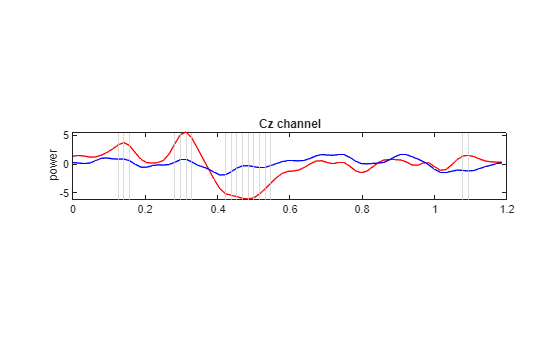


test_nontarget = segments_nontarget(:, :, 901:1800);
test_target = segments_target(:, :, 201:400);

Cz_non_tar = train_nontarget(2, :, :);
Cz_tar = train_target(2, :, :);
Cz_mean_non_tar = mean(train_nontarget(2, :, :), 3);
Cz_mean_tar = mean(train_target(2, :, :), 3);

function [diff,p_values] = stat_diff(tar, non_tar)
    num_timesteps = size(tar, 2);
    diff = zeros(num_timesteps, 1);
    p_values = zeros(num_timesteps, 1);

    for i = 1:num_timesteps
        time_tar = tar(:, i, :);
        time_non = non_tar(:, i, :);
        
        [p, h] = ranksum(time_tar(:), time_non(:), 'alpha', (0.01/num_timesteps)); %Bonferroni correction
        
        % we store a list that has a 1 if a timestep was significantly
        % differena and 0 if it was not
        diff(i) = h;
        p_values(i) = p;
    end
end

[Cz_stats, Cz_ps] = stat_diff(Cz_tar, Cz_non_tar);

function plot_stats(stats, t)
    % whenever the stats are 1 (significant), we take that specific time,
    % measured in seconds, so it can be plotted
    sig_times = t(stats == 1);
    
    if ~isempty(sig_times)
        xline(sig_times, 'Color', [0.8 0.8 0.8], 'HandleVisibility', 'off');
    end
end

figure;

subplot(3, 1, 2);
plot(t, Cz_mean_tar, 'r');
hold on
plot(t, Cz_mean_non_tar, 'b');
hold on
plot_stats(Cz_stats, t)
hold off
title('Cz channel')
ylabel('power')



%19-24
%29-36


[M_1, I_1] = min(Cz_ps(19:24)) % index 21

M_1 = 3.5877e-11

I_1 = 3

[M_2, I_2] = min(Cz_ps(29:36)) % index 32

M_2 = 2.4385e-18

I_2 = 4

% Extract the corresponding time points for the minimum p-values
train_nontarget_dimA = train_nontarget(2, 21, :)

train_nontarget_dimA = train_nontarget_dimA(:,:,1) =

  -13.2899


train_nontarget_dimA(:,:,2) =

    2.6729


train_nontarget_dimA(:,:,3) =

   -9.5763


train_nontarget_dimA(:,:,4) =

  -13.6571


train_nontarget_dimA(:,:,5) =

    5.0387


train_nontarget_dimA(:,:,6) =

   20.5203


train_nontarget_dimA(:,:,7) =

    8.7889


train_nontarget_dimA(:,:,8) =

   10.6511


train_nontarget_dimA(:,:,9) =

   -1.2081


train_nontarget_dimA(:,:,10) =

   11.1075


train_nontarget_dimA(:,:,11) =

    5.3192


train_nontarget_dimA(:,:,12) =

   -7.5551


train_nontarget_dimA(:,:,13) =

   -3.3299


train_nontarget_dimA(:,:,14) =

   -0.6597


train_nontarget_dimA(:,:,15) =

   -5.9899


train_nontarget_dimA(:,:,16) =

   -0.6886


train_nontarget_dimA(:,:,17) =

   -7.8328


train_nontarget_dimA(:,:,18) =

    5.2315


train_nontarget_dimA(:,:,19) =

   -1.3870


train_nontarget_dimA(:,:,20) =

   -4.2658


train_nontarget_dimA(:,:,21) =

   21.1534


train_nontarget_dimA(:,:,22) =

   -7.599

train_target_dimA = train_target(2, 21, :)

train_target_dimA = train_target_dimA(:,:,1) =

   20.7418


train_target_dimA(:,:,2) =

    0.3498


train_target_dimA(:,:,3) =

    0.7226


train_target_dimA(:,:,4) =

    6.8864


train_target_dimA(:,:,5) =

  -14.4389


train_target_dimA(:,:,6) =

   13.6350


train_target_dimA(:,:,7) =

    9.2488


train_target_dimA(:,:,8) =

   14.2676


train_target_dimA(:,:,9) =

    3.4609


train_target_dimA(:,:,10) =

    7.7547


train_target_dimA(:,:,11) =

   -3.4376


train_target_dimA(:,:,12) =

    6.6983


train_target_dimA(:,:,13) =

   27.6144


train_target_dimA(:,:,14) =

    0.7043


train_target_dimA(:,:,15) =

   20.5042


train_target_dimA(:,:,16) =

    5.4827


train_target_dimA(:,:,17) =

   13.7580


train_target_dimA(:,:,18) =

   -1.1425


train_target_dimA(:,:,19) =

    5.9397


train_target_dimA(:,:,20) =

  -11.2449


train_target_dimA(:,:,21) =

    3.8593


train_target_dimA(:,:,22) =

   -1.9507


train_target_dimA(:,:,23) =

   11.2620


train_target_dimA(:,:,2

train_nontarget_dimB = train_nontarget(2, 32, :)

train_nontarget_dimB = train_nontarget_dimB(:,:,1) =

    9.1433


train_nontarget_dimB(:,:,2) =

   12.0317


train_nontarget_dimB(:,:,3) =

    6.8399


train_nontarget_dimB(:,:,4) =

  -12.5965


train_nontarget_dimB(:,:,5) =

    8.4523


train_nontarget_dimB(:,:,6) =

   -3.8231


train_nontarget_dimB(:,:,7) =

  -11.3213


train_nontarget_dimB(:,:,8) =

   -4.9981


train_nontarget_dimB(:,:,9) =

    5.6317


train_nontarget_dimB(:,:,10) =

    2.3970


train_nontarget_dimB(:,:,11) =

    3.2681


train_nontarget_dimB(:,:,12) =

    7.3198


train_nontarget_dimB(:,:,13) =

   -6.9498


train_nontarget_dimB(:,:,14) =

    0.7811


train_nontarget_dimB(:,:,15) =

   -2.6389


train_nontarget_dimB(:,:,16) =

    9.8216


train_nontarget_dimB(:,:,17) =

   18.8923


train_nontarget_dimB(:,:,18) =

   -3.5016


train_nontarget_dimB(:,:,19) =

  -10.9293


train_nontarget_dimB(:,:,20) =

    5.3794


train_nontarget_dimB(:,:,21) =

   -5.5726


train_nontarget_dimB(:,:,22) =

  -15.515

train_target_dimB = train_target(2, 32, :)

train_target_dimB = train_target_dimB(:,:,1) =

  -14.6804


train_target_dimB(:,:,2) =

   17.4407


train_target_dimB(:,:,3) =

  -11.2248


train_target_dimB(:,:,4) =

   -5.5091


train_target_dimB(:,:,5) =

   -8.7989


train_target_dimB(:,:,6) =

   -8.6555


train_target_dimB(:,:,7) =

    6.2794


train_target_dimB(:,:,8) =

   -9.8904


train_target_dimB(:,:,9) =

   -8.1904


train_target_dimB(:,:,10) =

   -7.1683


train_target_dimB(:,:,11) =

    5.9227


train_target_dimB(:,:,12) =

  -20.5115


train_target_dimB(:,:,13) =

  -20.2851


train_target_dimB(:,:,14) =

   -1.7366


train_target_dimB(:,:,15) =

  -16.2237


train_target_dimB(:,:,16) =

   -9.2707


train_target_dimB(:,:,17) =

  -13.6488


train_target_dimB(:,:,18) =

   -8.7306


train_target_dimB(:,:,19) =

    5.6028


train_target_dimB(:,:,20) =

   -6.5920


train_target_dimB(:,:,21) =

  -14.7883


train_target_dimB(:,:,22) =

   -4.8269


train_target_dimB(:,:,23) =

   -8.8335


train_target_dimB(:,:,2

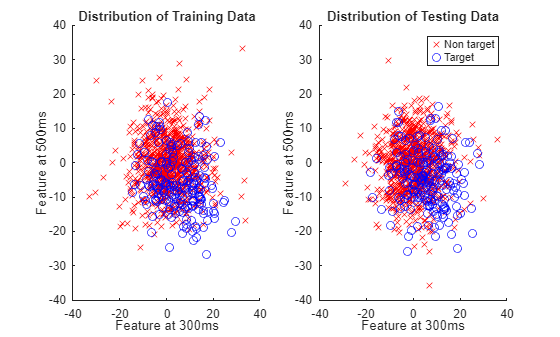


test_nontarget_dimA = test_nontarget(2, 21, :);
test_target_dimA = test_target(2, 21, :);
test_nontarget_dimB = test_nontarget(2, 32, :);
test_target_dimB = test_target(2, 32, :);

% Plot training data
figure;
subplot(1,2,1);
scatter(train_nontarget_dimA(:), train_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(train_target_dimA(:), train_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;
xlim([-40, 40])
ylim([-40 40])

title('Distribution of Training Data');
xlabel('Feature at 300ms');
ylabel('Feature at 500ms');

% Plot test data
subplot(1,2,2);
scatter(test_nontarget_dimA(:), test_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(test_target_dimA(:), test_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;
xlim([-40, 40])
ylim([-40 40])

title('Distribution of Testing Data');
legend('Non target', 'Target');
xlabel('Feature at 300ms');
ylabel('Feature at 500ms');

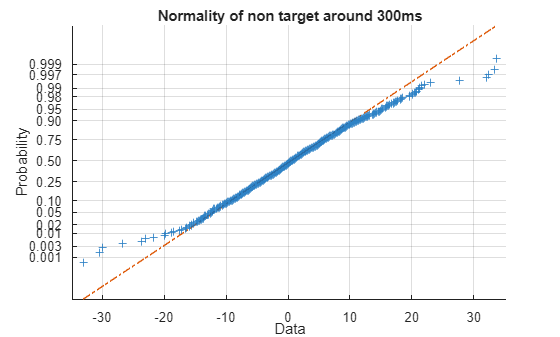

figure;
normplot(train_nontarget_dimA(:))
title('Normality of non target around 300ms');

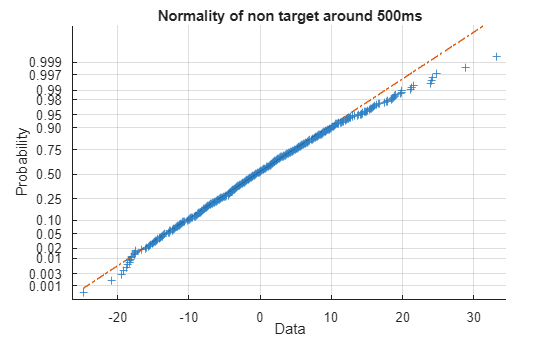


normplot(train_nontarget_dimB(:))
title('Normality of non target around 500ms');

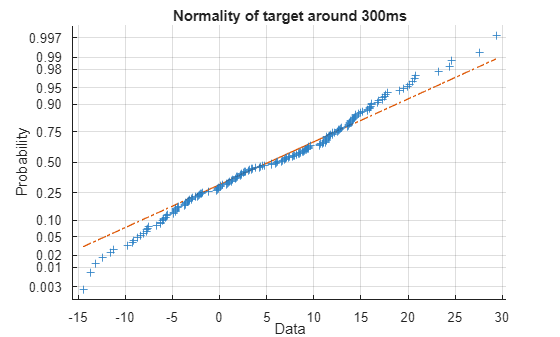


normplot(train_target_dimA(:))
title('Normality of target around 300ms');

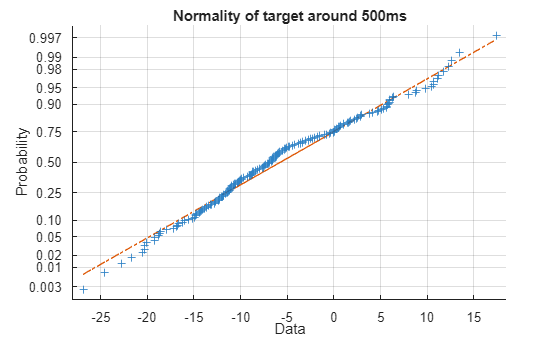


normplot(train_target_dimB(:))
title('Normality of target around 500ms');

X_train_non = [train_nontarget_dimA(:), train_nontarget_dimB(:)]

X_train_non =   -13.2899    9.1433
    2.6729   12.0317
   -9.5763    6.8399
  -13.6571  -12.5965
    5.0387    8.4523
   20.5203   -3.8231
    8.7889  -11.3213
   10.6511   -4.9981
   -1.2081    5.6317
   11.1075    2.3970
    5.3192    3.2681
   -7.5551    7.3198
   -3.3299   -6.9498
   -0.6597    0.7811
   -5.9899   -2.6389


X_train_tar = [train_target_dimA(:), train_target_dimB(:)]

X_train_tar =    20.7418  -14.6804
    0.3498   17.4407
    0.7226  -11.2248
    6.8864   -5.5091
  -14.4389   -8.7989
   13.6350   -8.6555
    9.2488    6.2794
   14.2676   -9.8904
    3.4609   -8.1904
    7.7547   -7.1683
   -3.4376    5.9227
    6.6983  -20.5115
   27.6144  -20.2851
    0.7043   -1.7366
   20.5042  -16.2237


X_train = cat(1, X_train_non, X_train_tar)

X_train =   -13.2899    9.1433
    2.6729   12.0317
   -9.5763    6.8399
  -13.6571  -12.5965
    5.0387    8.4523
   20.5203   -3.8231
    8.7889  -11.3213
   10.6511   -4.9981
   -1.2081    5.6317
   11.1075    2.3970
    5.3192    3.2681
   -7.5551    7.3198
   -3.3299   -6.9498
   -0.6597    0.7811
   -5.9899   -2.6389


Y_train = cat(1, -1*ones(size(train_nontarget_dimA(:))), ones(size(train_target_dimA(:)))) % Labels for training data

Y_train =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1



X_test_non = [test_nontarget_dimA(:), test_nontarget_dimB(:)]

X_test_non =    -6.0331   12.9038
   -0.9440   -5.2800
   -4.5329  -11.8939
  -10.4567   -9.5304
   -4.4436   -7.6793
   -8.0750   -7.0555
    2.6032   -3.3835
    2.1247   -8.8231
    8.8483    2.0315
    4.0827   -3.8187
   13.6772    1.8664
    3.6323   -3.5251
    6.6439   -7.9319
    3.2834   -3.6498
   -2.9029   -2.6100


X_test_tar = [test_target_dimA(:), test_target_dimB(:)]

X_test_tar =    -3.8353   -2.4963
    6.1047  -11.2434
   -0.0543  -10.1607
   -9.1283   -3.2577
    5.0243    7.3124
    1.8582  -10.0727
   12.7527   -2.3351
   13.1043  -13.5481
   25.0172  -13.3934
   28.1706   -0.5601
   10.5272    6.6322
   18.3200   -3.0674
   23.9725    5.7587
    6.3745  -18.2660
   10.4431   -0.1233


X_test = cat(1, X_test_non, X_test_tar)

X_test =    -6.0331   12.9038
   -0.9440   -5.2800
   -4.5329  -11.8939
  -10.4567   -9.5304
   -4.4436   -7.6793
   -8.0750   -7.0555
    2.6032   -3.3835
    2.1247   -8.8231
    8.8483    2.0315
    4.0827   -3.8187
   13.6772    1.8664
    3.6323   -3.5251
    6.6439   -7.9319
    3.2834   -3.6498
   -2.9029   -2.6100


Y_test = cat(1, -1*ones(size(test_nontarget_dimA(:))), ones(size(test_target_dimA(:)))) % Labels for testing data

Y_test =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1



[acc_train, acc_test, w, b, line] = custom_LDA(X_train', Y_train', X_test', Y_test');

Test Set Accuracy: 81.91%
Train Set Accuracy: 83.09%


result = sign(w' * X_test' + b);
results_c1 = result(Y_test == -1)

results_c1 =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


results_c2 = result(Y_test == 1)

results_c2 =     -1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1


correct_c1 = (results_c1 == -1)

correct_c1 = 1×900 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


correct_c2 = (results_c2 == 1)

correct_c2 = 1×200 logical array
   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0



accuracy_c1 = sum(correct_c1) / length(results_c1)

accuracy_c1 = 0.9822

accuracy_c2 = sum(correct_c2) / length(results_c2)

accuracy_c2 = 0.0850

accuracy = accuracy_c1 * 0.5 + accuracy_c2 * 0.5

accuracy = 0.5336


fprintf('Balanced test Set Accuracy: %.2f%%\n', accuracy * 100);

Balanced test Set Accuracy: 53.36%


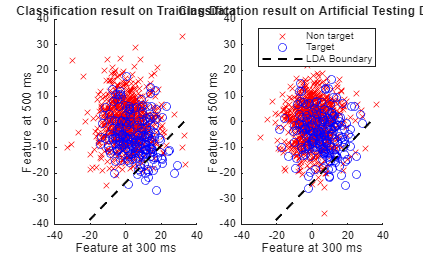

% Plot results
% Plot training data
figure;
subplot(1,2,1);
scatter(train_nontarget_dimA(:), train_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(train_target_dimA(:), train_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot(line.x, line.y, '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Training Data');
xlabel('Feature at 300 ms');
ylabel('Feature at 500 ms');
xlim([-40, 40])
ylim([-40 40])

% Plot test data
subplot(1,2,2);
scatter(test_nontarget_dimA(:), test_nontarget_dimB(:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(test_target_dimA(:), test_target_dimB(:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot(line.x, line.y, '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Artificial Testing Data');
legend('Non target', 'Target', 'LDA Boundary');
xlabel('Feature at 300 ms');
ylabel('Feature at 500 ms');
xlim([-40, 40])
ylim([-40 40])